%计算考虑化学作用后的n聚体系下锁死的概率
clc;
clear all

n=3;
l=n+0.5;
count=1e4;
%AM为考察互锁结构的邻接矩阵 
AM=ones(n)-eye(n);
k=1; %k表示E的多少倍
MC_result=[];

Ct=1;
%Ct为初始投入单体的浓度
A=1; 
%将能量G拆成两部分，一部分为笼盖间相互作用E，其余的为另一部分
%K=exp(-G/RT)=A*exp(-E/RT)
%K和转化率p之间满足:K=p/(Ct*(1-p)^2)
DP=[];


for l=n:0.1:n+1
    for k = 0:0.1:2
        MC_result_l=MC_chem_prob(n,count,AM,l,k); %锁死概率

        K=A*exp((5000*k)/(8.31*298));
        p=(2*K*Ct+1-sqrt(4*K*Ct+1))/(2*K*Ct);
        DP=[DP,(1-(p^n)*MC_result_l)/(1-p)];

        MC_result=[MC_result,MC_result_l]
    end
end

MC_result = 0.5072

MC_result =     0.5072    0.4563


MC_result =     0.5072    0.4563    0.4763


MC_result =     0.5072    0.4563    0.4763    0.4932


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072    0.5248


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072    0.5248    0.6153


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072    0.5248    0.6153    0.6974


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072    0.5248    0.6153    0.6974    0.7687


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072    0.5248    0.6153    0.6974    0.7687    0.8273


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072    0.5248    0.6153    0.6974    0.7687    0.8273    0.8735


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072    0.5248    0.6153    0.6974    0.7687    0.8273    0.8735    0.9085


MC_result =     0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668    0.8934    0.9153    0.9331    0.9475    0.9589    0.9680    0.9752    0.9808    0.9852    0.9886    0.9913    0.9933    0.5072    0.5248    0.6153    0.6974    0.7687    0.8273    0.8735    0.9085


MC_result = 1×52
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×53
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×54
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×55
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×56
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×57
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×58
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×59
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×60
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×61
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×62
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×63
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×64
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×65
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×66
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×67
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×68
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×69
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×70
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×71
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×72
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×73
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×74
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×75
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×76
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×77
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×78
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×79
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×80
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×81
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×82
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×83
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×84
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×85
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×86
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×87
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×88
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×89
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×90
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×91
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×92
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×93
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×94
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×95
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×96
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×97
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×98
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×99
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×100
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×101
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×102
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×103
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×104
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×105
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×106
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×107
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×108
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×109
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×110
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×111
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×112
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×113
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×114
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×115
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×116
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×117
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×118
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×119
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×120
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×121
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×122
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×123
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×124
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×125
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×126
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×127
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×128
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×129
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×130
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×131
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×132
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×133
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×134
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×135
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×136
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×137
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×138
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×139
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×140
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×141
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×142
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×143
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×144
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×145
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×146
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×147
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×148
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×149
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×150
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×151
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×152
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×153
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×154
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×155
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×156
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×157
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×158
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×159
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×160
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×161
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×162
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×163
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×164
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×165
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×166
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×167
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×168
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×169
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×170
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×171
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×172
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×173
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×174
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×175
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×176
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×177
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×178
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×179
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×180
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×181
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×182
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×183
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×184
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×185
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×186
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×187
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×188
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×189
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×190
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×191
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×192
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×193
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×194
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×195
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×196
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×197
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×198
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×199
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×200
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×201
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×202
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×203
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×204
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×205
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×206
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×207
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×208
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×209
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×210
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×211
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×212
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×213
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×214
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×215
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×216
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×217
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×218
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×219
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×220
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×221
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×222
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×223
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×224
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×225
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×226
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×227
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×228
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×229
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×230
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668


MC_result = 1×231
    0.5072    0.4563    0.4763    0.4932    0.5067    0.5184    0.5300    0.5423    0.5557    0.5702    0.5856    0.6019    0.6187    0.6359    0.6534    0.6709    0.6883    0.7055    0.7224    0.7388    0.7547    0.5072    0.5036    0.5724    0.6379    0.6979    0.7507    0.7961    0.8346    0.8668



%笼长l,作用力强度e和锁死概率的关系
l=n:0.1:n+1;
k=0:0.5:10;
[L,K]=meshgrid(l,k);
Z=reshape(MC_result,[21 11])

Z = 21×11
    0.5072    0.5072    0.5072    0.5072    0.5072    0.5072    0.5072    0.5072    0.5072    0.5072    0.5072
    0.4563    0.5036    0.5248    0.5317    0.5324    0.5314    0.5306    0.5306    0.5312    0.5321    0.5328
    0.4763    0.5724    0.6153    0.6293    0.6281    0.6204    0.6116    0.6043    0.5990    0.5952    0.5925
    0.4932    0.6379    0.6974    0.7166    0.7156    0.7044    0.6898    0.6764    0.6658    0.6579    0.6519
    0.5067    0.6979    0.7687    0.7899    0.7890    0.7768    0.7594    0.7421    0.7277    0.7168    0.7086
    0.5184    0.7507    0.8273    0.8483    0.8475    0.8357    0.8180    0.7990    0.7827    0.7701    0.7606
    0.5300    0.7961    0.8735    0.8928    0.8920    0.8814    0.8650    0.8464    0.8297    0.8167    0.8069
    0.5423    0.8346    0.9085    0.9254    0.9247    0.9157    0.9014    0.8845    0.8686    0.8562    0.8469
    0.5557    0.8668    0.9344    0.9487    0.9481    0.9407    0.9288    0.9143    0.9001    0.8889  

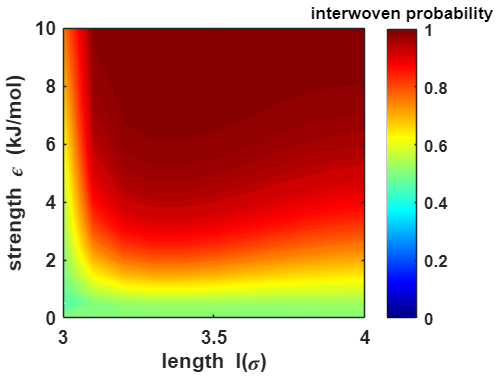

[C,h]=contourf(L,K,Z,50,'--','ShowText','off','LabelSpacing',1000);
h.LevelList=round(h.LevelList,2);  %等高线数值保留小数点后两位
set(h, 'edgecolor','none');
clabel(C,h);

c1=colorbar;
clim([0 1])
% clim([0.5 1]); （colorbar范围）
colormap("jet");

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('strength \epsilon (kJ/mol)','FontName','arial','FontWeight','bold');

set(get(c1,'title'),'string','interwoven probability','FontWeight','bold','FontName','arial')



%笼长l,作用力强度e和聚合度DP的关系
l=n:0.1:n+1;
k=0:0.5:10;
[L,K]=meshgrid(l,k);
Z=reshape(DP,[21 11])

Z = 21×11
    1.5723    1.5723    1.5723    1.5723    1.5723    1.5723    1.5723    1.5723    1.5723    1.5723    1.5723
    1.6574    1.6516    1.6490    1.6481    1.6480    1.6481    1.6482    1.6482    1.6482    1.6480    1.6480
    1.7423    1.7262    1.7190    1.7167    1.7169    1.7182    1.7196    1.7209    1.7217    1.7224    1.7228
    1.8335    1.8014    1.7882    1.7839    1.7841    1.7866    1.7899    1.7928    1.7952    1.7969    1.7983
    1.9316    1.8760    1.8555    1.8493    1.8496    1.8531    1.8582    1.8632    1.8674    1.8705    1.8729
    2.0363    1.9493    1.9206    1.9128    1.9131    1.9175    1.9241    1.9312    1.9373    1.9421    1.9456
    2.1472    2.0205    1.9837    1.9745    1.9749    1.9799    1.9877    1.9966    2.0045    2.0107    2.0154
    2.2637    2.0890    2.0448    2.0347    2.0351    2.0405    2.0490    2.0591    2.0686    2.0761    2.0816
    2.3852    2.1543    2.1042    2.0935    2.0940    2.0995    2.1082    2.1191    2.1296    2.1379  

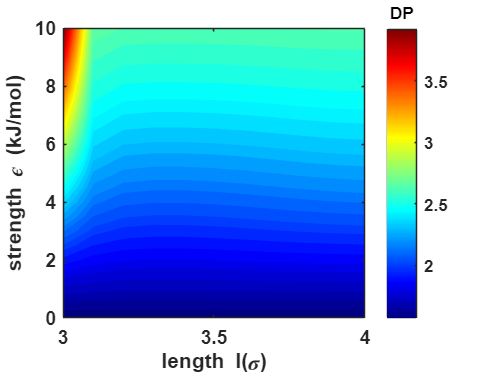

[C,h]=contourf(L,K,Z,50,'--','ShowText','off','LabelSpacing',1000);
h.LevelList=round(h.LevelList,2);  %等高线数值保留小数点后两位
set(h, 'edgecolor','none');
clabel(C,h);

c1=colorbar;

colormap("jet");

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('strength \epsilon (kJ/mol)','FontName','arial','FontWeight','bold');

set(get(c1,'title'),'string','DP','FontWeight','bold','FontName','arial')


save("MC_colormap_probability_DP_interlock3","MC_result","DP")

function BM=border(n)
%给定阶数n，生成对映的边界矩阵BM（border matrix）
%该矩阵对映了邻接矩阵AM上三角矩阵中处于0和1边界中1的位置
   BM=zeros(n);

if n==2
   BM(:,:,end+1)=[0 1;0 0];
end

if n>2
   A=border(n-1);
   C=zeros(1,n);
   for i=1:size(A,3)
        B=[zeros(n-1,1),A(:,:,i)];
        for j=2:find(B(1,:)==1)
            C(1,j)=1;
            BM(:,:,end+1)=[C;B];
            C=zeros(1,n);
        end
   end
end
BM(:,:,1)=[];
end
%-------------------------------------------------
function AM=adj_mat(n)
%根据边界矩阵BM，写出n阶所有邻接矩阵AM
BM=border(n);
AM=zeros(n);

for i=1:size(BM,3)
    A=BM(:,:,i);
    for j=1:n-1
        for k=j+1:find(A(j,:)==1)
            A(j,k)=1;
        end
    end
    A=A+A';
    AM(:,:,end+1)=A;
end
AM(:,:,1)=[];
end



%-------------------------------------------------
function signal=cat_config(AM,seq,l)
%根据邻接矩阵AM，判断随机给出单元位置坐标的数列是否属于该构型
ran=sort(seq);

signal=1;

for i=1:size(AM,1)
    pos1=find(AM(i,:)==1);
    pos2=find(AM(i,:)==0);
    pos2(pos2==i)=[];
    for j=1:length(pos1)
        if abs(ran(i)-ran(pos1(j)))<=l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end

    for j=1:length(pos2)
        if abs(ran(i)-ran(pos2(j)))>l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end
end

signal;
%signal=1则属于该构型，反之不属于
end


%-------------------------------------------------
function a= E(r) %定义特定的势能函数E(r)
    e=5000;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

%-------------------------------------------------
function b=P(r,k) %定义相应的概率分布函数P(r) 
%k表示E的多少倍
    b=exp(-k*E(r)/(8.31*298));
end

%-------------------------------------------------
function f=Gauss(miu,sigma,x) %计算Gauss分布在x处的y值
    f=1/(sqrt(2*pi)*sigma)*exp(-(x-miu)^2/(2*sigma^2));
end

%-------------------------------------------------
function W=Ptotal(pos_start,l,k) %根据互锁单元初始位置（左盖位置）计算互锁结构的总概率密度
%k表示E的多少倍
    density=[];
    pos_end=pos_start+l; %互锁单元末尾位置（右盖子）
    Position=sort([pos_start pos_end]);
    for i=2:length(Position)
        density=[density,P(Position(i)-Position(i-1),k)];
    end
    W=prod(density);
end

%-------------------------------------------------
function Sigma = buildCovarianceMatrix(n, L, lambda)
    % 构建指数衰减协方差矩阵
    Sigma = zeros(n, n);
    sigma = L / 3; % 标准差
    for i = 1:n
        for j = 1:n
            Sigma(i, j) = sigma^2 * exp(-abs(i-j)/lambda);
        end
    end
    % 正则化以确保正定性
    Sigma = Sigma + 1e-6 * eye(n);
end


%-------------------------------------------------
function MC_result_l=MC_chem_prob(n,count,AM,l,k)
%用monte carlo方法计算化学概率
%n：聚合度； count:采样次数；AM：计算的互锁结构的邻接矩阵; k表示E的多少倍
%这里计算的l是从n到n+1

%对于蒙特卡洛的结果进行多次重复（trial）



    L=(n-1)*l;    
    MC_result_l=[]; %特定l下MC计算出的概率结果

    for trial=1:1 %计算5此MC结果，取平均
        count1=0;
        count2=0;    
        n_mer=0;
        config=0;
        
        %尝试通过重要性采样的方法提高蒙特卡洛方法的精度
        miu = zeros(1, n-1); % 均值向量（初始化为0）
        lambda = 1; % 相关性衰减系数
        Sigma = buildCovarianceMatrix(n-1, L, lambda); % 协方差矩阵
        rng('default')  % For reproducibility
    
        %生成样本
        samples = mvnrnd(miu, Sigma, count); % 从多维高斯分布采样
        samples = max(min(samples, L), -L); % 约束在[-L, L]内
         
        X=samples; %第i列表示xi
        
        for i=1:count
            
            R=[0 X(i,:)]; %提取一组[x1,x2,x3,...]坐标
            start=sort(R);
            signal=1;
             
            %计算采样权重samplingweight，对应
            samplingweight=mvnpdf(X(i,:),miu,Sigma);
        
            %判断随机排列的n个单体是否生成n聚互锁结构(如是,signal=1)
            for i=2:size(start,2)
                if start(i)<=start(i-1)+l
                    signal=signal*1;
                else
                    signal=signal*0;
                    break
                end
            end
        
            %判断随机生成的n聚结构是否满足AM的链接结构    
            if signal==1 
        
                %每次采样的贡献为概率密度权重除以采样权重
                n_mer=n_mer+Ptotal(R,l,k)/samplingweight; 
                count1=count1+1;
        
                if cat_config(AM,start,l)==1
                    config=config+Ptotal(R,l,k)/samplingweight;
                    count2=count2+1;
                end
        
            end 
            
        end
        
        n_mer;
        config;
        
        probability=config/n_mer; %生成AM互锁结构的化学概率
        efficiency1=count1/count; %蒙特卡洛方法有效计算的占比
        MC_result_l=[MC_result_l;probability];
    end
MC_result_l;
end
